close all; clear; clc;

# Step Data Test 

**filename**: steps_20180628.mlx

**keywords:** 

**file created by:** {20180629, Edmonds}

**last updated on:** {20180701}

**primary purpose:**  This script allows you to set the min and max PWM and the number of steps you want to record between them. You can't directly set at what PWM/throttle setting you want the data points recorded. But if you want it in 10% increments you can set the number to 11 (counting 0%). If the number of steps is set right, I think this would show results similar to Tom's tests. 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** Rotational Speed was calculated in RPM, need to convert to rad/sec

Don't think I tore the load cell or voltage before running tests

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002285947263;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('StepsTest.mat');
time = StepsTest(:,1);          % [sec]
ESC_us = StepsTest(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = StepsTest(:,3);             % [ft.lbf]
T = StepsTest(:,4);             % [lbf]
Input_V = StepsTest(:,5);       % [Volts]
Input_A = StepsTest(:,6);       % [Amps]
rot_speed_RPM = StepsTest(:,7);     % [rad/sec]
% Convert RPM to rad/sec
rot_speed = rot_speed_RPM .* (pi/30);

P_in_W = StepsTest(:,8);        % [Watts]
P_out_W = StepsTest(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = StepsTest(:,10);    % [%]
Prop_Eff = StepsTest(:,11);     % [lbf/Watts]
Overall_Eff = StepsTest(:,12);  % [lbf/Watts]  
Motor_Temp = StepsTest(:,13);   % [F]


## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

{This is the section for generating output tables, plots, etc.}

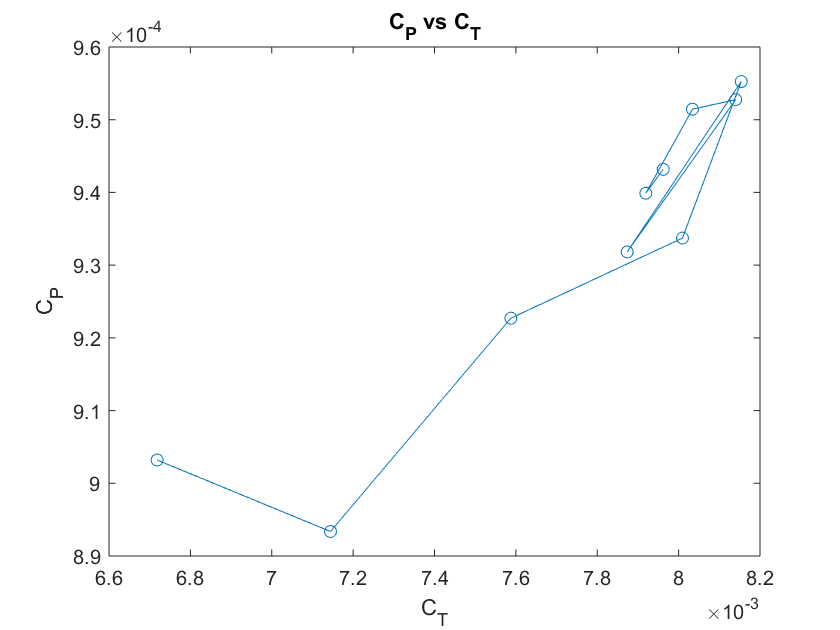



figure(1)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

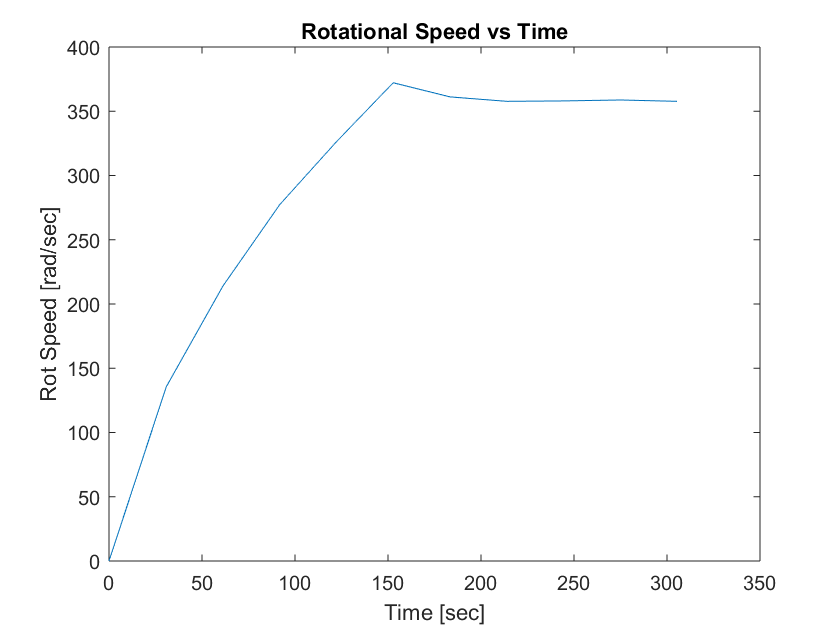

figure(2)
plot(time, rot_speed);
title('Rotational Speed vs Time'); xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]')

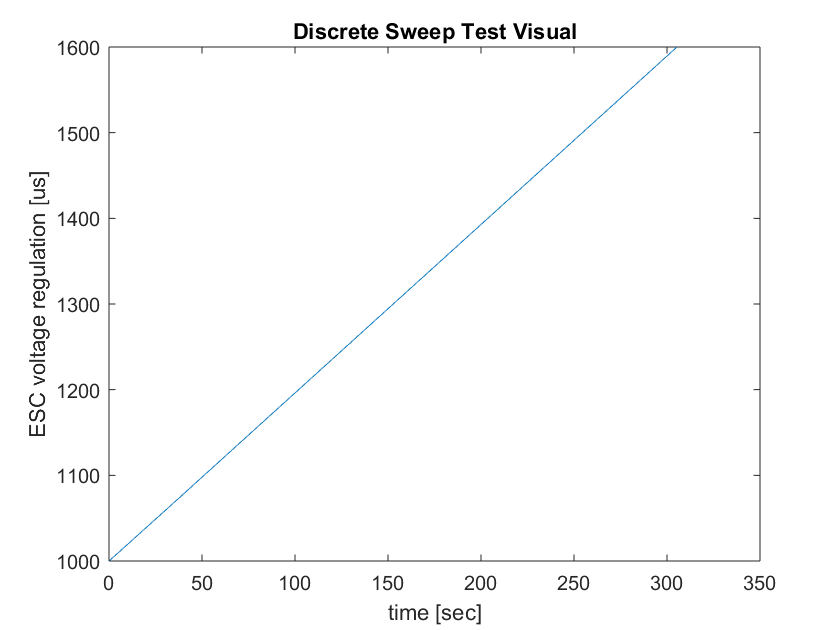

figure(3)
plot(time, ESC_us); title('Discrete Sweep Test Visual'); 
xlabel('time [sec]'); ylabel('ESC voltage regulation [us]')

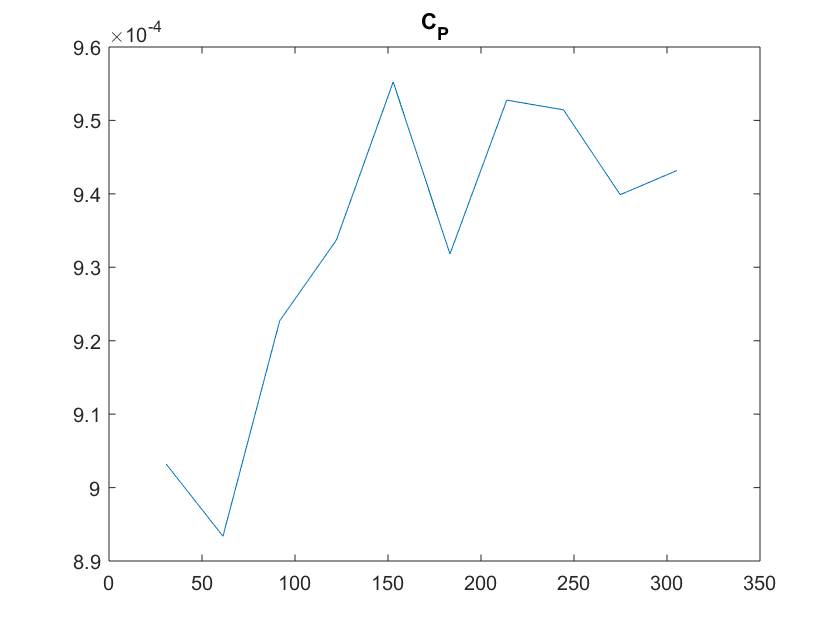





figure(4)
plot(time, C_P);
title('C_P');

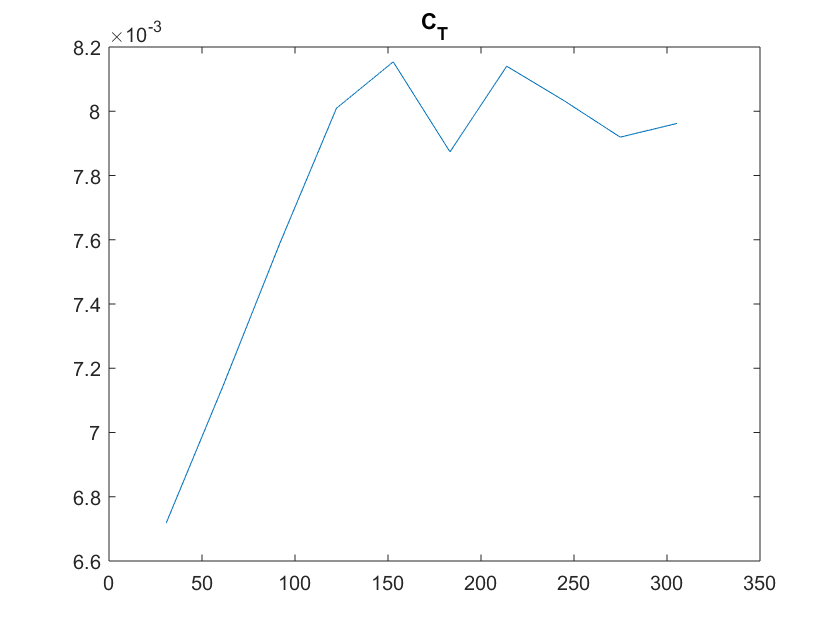


figure(5)
plot(time, C_T);
title('C_T');

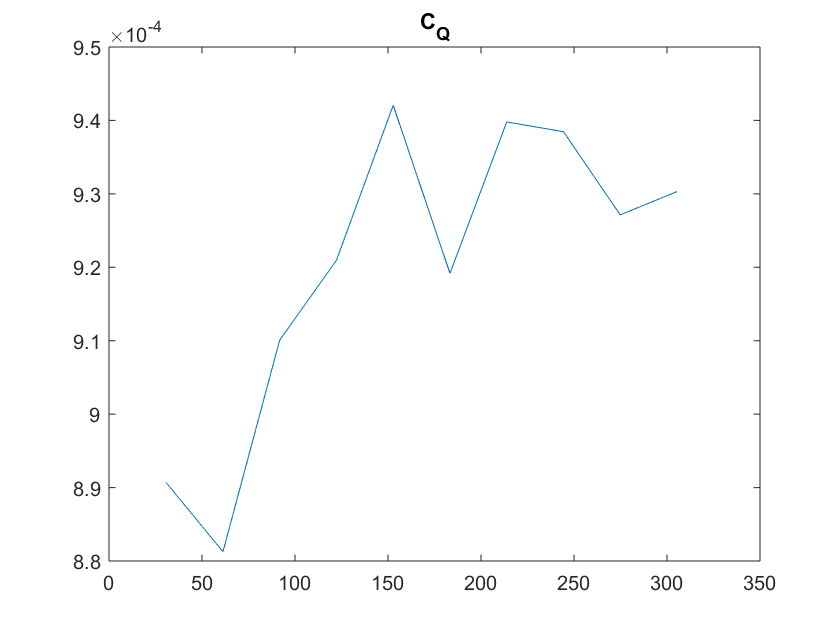


figure(6)
plot(time, C_Q);
title('C_Q');

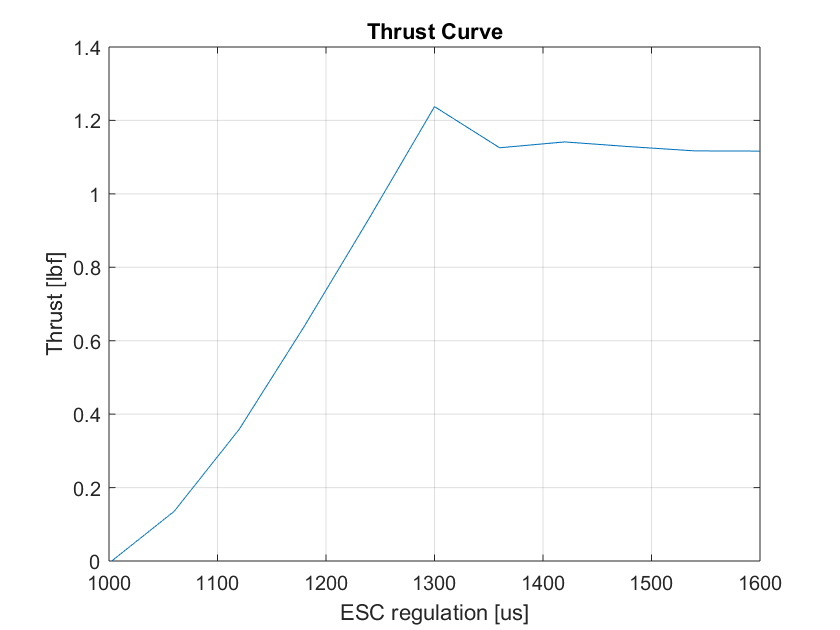

figure(7)
plot(ESC_us, T);
title('Thrust Curve'); xlabel('ESC regulation [us]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);